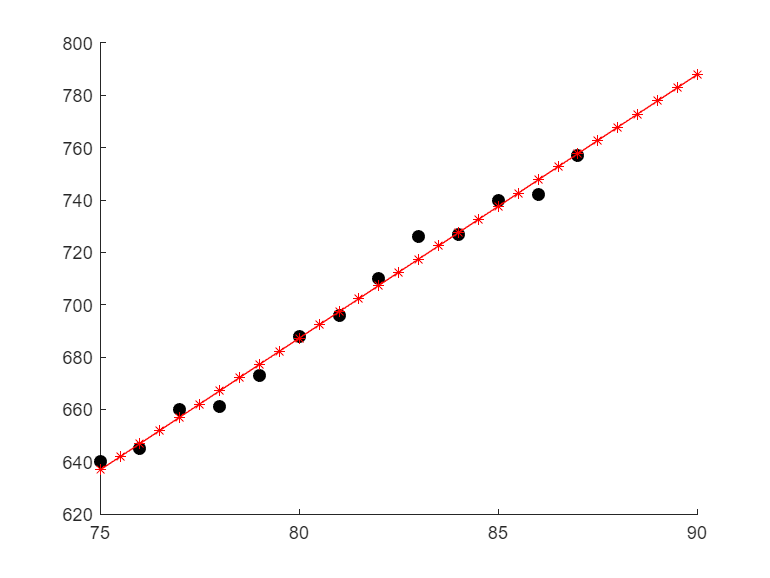

x = 75:87;
%x = x';
y = [640 645 660 661 673 688 696 710 726 727 740 742 757];
sz = 50;
scatter(x,y,sz,"black","filled","o");
n = length(x);
xm = mean(x);
ym = mean(y);
sx = sqrt(sum((x - xm).^2)/(n - 1));
sy = sqrt(sum((y - ym).^2)/(n - 1));
r = sum((x - xm).*(y - ym))/(n - 1)/(sx*sy);
a = r*sy/sx;
b = ym-a*xm;
xx = 75:0.5:90;
yy = a*xx+b;
hold on
plot(xx,yy,'r-*')

x = x';
X = [ones(n,1),x];
Y = y';
w = X\Y;

M = [1 2 3; 4 5 6; 7 8 9];
re